Prof. Dr. Ralf Hielscher 

Erik Wünsche

TU Bergakademie Freiberg

Summer Semester 2025

# Mathematical Image Processing - Exercise Sheet 5

Download the zip file` sheet5.zip `with the images for the following tasks from OPAL. Please make sure your current working directory (Working directory/Current Folder) in MATLAB matches the folder where the exercises are located.

**Important Tips:**

- Use **Ctrl+Enter** to run a section.

- Use **Ctrl+Alt+Enter** to insert section breaks.

- Use **F9** to execute highlighted code in the command window.

#### Exercise 1: (Non-linear Smoothing Filters)

You will need the Image Processing Toolbox of Matlab (Installation: Home -> Add-Ons -> Image Processing Toolbox).

In the following we will take a look on different nonlinear filters. Therefore we will test this filters on the images` capybara_Gaussian.png `(white Gaussian noise) and` capybara_SaP.png `(salt-and-pepper noise), similarly as we did in exercise sheet 2 with linear filters.

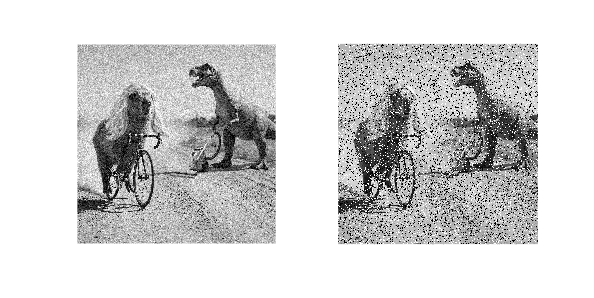

% load and plot the input images
imgG = double(imread('capybara_Gaussian.png'))/255;
imgSaP = double(imread('capybara_SaP.png'))/255;
fig = figure;
fig.Position(3:4) = [3000,1500];
subplot(1,2,1)
imshow(imgG)
subplot(1,2,2)
imshow(imgSaP)

a) **Median Filter**

The Median-Filter is the simplest example of a non-linear filter.

In exercise sheet 2 we allready implemented the method` median_filter(F,s)`.

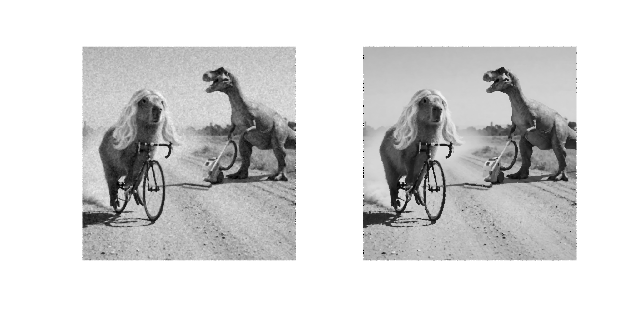

% apply the median filter to the images
fig = figure;
fig.Position(3:4) = [3000,1500];
subplot(1,2,1)
imshow(median_filter(imgG,2))
subplot(1,2,2)
imshow(median_filter(imgSaP,2))

b) **Bilateral Filter**

The Bilateral-Filter is an adaptive filter, i.e. it is adapted to the properties of the image. This means that the filter weights depend on the colour values.

Let a discrete image $F\colon \mathcal G \to \mathbb R$ be given. Then the bilateral filter creates an image $U\colon \mathcal G \to \mathbb R$ where


$$U(k,l) := \sum_{(i,j)\in\mathcal{N}(k,l)} \frac{\omega_s((k,l)-(i,j)) \, \omega_r(F(k,l)-F(i,j))}{\sum_{(u,v)\in\mathcal N(k,l)} \omega_s((k,l)-(u,v)) \, \omega_r(F(k,l)-F(u,v))}\,F(i,j).$$


Notions:

- $\mathcal N(k,l)$ is the neighbourhood of the pixel $(k,l)^T \in \mathcal G$

- $\omega_s$ describes the spatial similarity

- $\omega_r$ describes the colour similarity

where $\omega_s$ and $\omega_r$ are described w.r.t. two Gaussian kernels


$$\omega_s(x) = \frac1{2\pi\sigma_s^2}\,\mathrm e^{-\|x\|^2/2\sigma_s^2}, \qquad \omega_r(x) = \frac1{2\pi\sigma_r^2}\,\mathrm e^{-\|x\|^2/2\sigma_r^2}.$$


Test the bilateral filter` imbilatfilt `which is already implemented in Matlab.

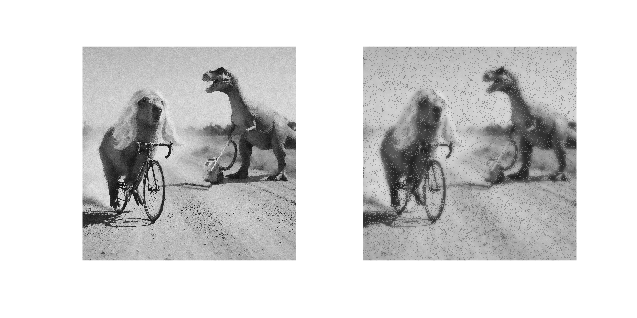

% apply the bilateral filter to the images
fig = figure;
fig.Position(3:4) = [3000,1500];
subplot(1,2,1)
imshow(imbilatfilt(imgG,0.03,5));
subplot(1,2,2)
imshow(imbilatfilt(imgSaP,0.3,5));

c) **Nonlocal Means Filter**

Each pixel of a given image is compared together with its neighbourhood to other regions in the image. A weight is determined in each case with respect to the similarity. The newly generated pixel value is then the weighted average of the central pixels in the regions.

Test the Nonlocal Mean Filter` imnlmfilt `already implemented in Matlab on the images` chess1.png `and` chess2.png`.

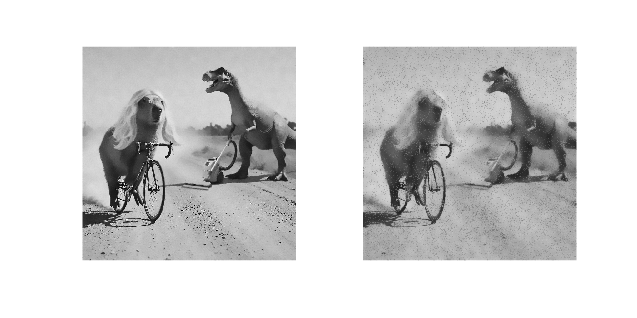

% apply the nonlocal means filter to the images
fig = figure;
fig.Position(3:4) = [3000,1500];
subplot(1,2,1)
imshow(imnlmfilt(imgG));
subplot(1,2,2)
imshow(imnlmfilt(imgSaP));

#### Exercise 2: (Tensor Products)

Let the matrices


$$A = \left(\begin{array}{rrr} 
1 & 4 & 7 \\ 
2 & 5 & 8 \\ 
3 & 6 & 9 \\ 
\end{array}\right) \qquad \text{and} \qquad B = \left(\begin{array}{rr} 
-1 & 1\\ 
2 & 3 \\ 
\end{array}\right)$$


be given. Compute the tensor product $C = A \otimes B$ with the matlab command ` kron`.

% TODO: tensor product

A = reshape((1:9),3,3);
B = [-1,1;2,3];
C = kron(A,B)

C =     -1     1    -4     4    -7     7
     2     3     8    12    14    21
    -2     2    -5     5    -8     8
     4     6    10    15    16    24
    -3     3    -6     6    -9     9
     6     9    12    18    18    27


Which is the size of the matrix $C$?

#### Exercise 3: (Edge Detection)

In the following we test some edge detectors on the image` coins.png`.

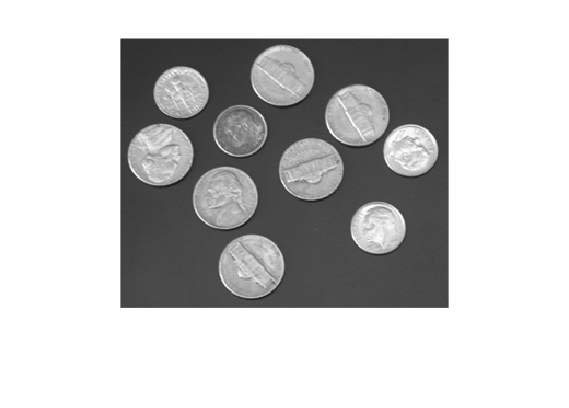

coins = double(imread('coins.png'))/255;
figure
imshow(coins)

An edge in the image means that the colour values of the image change very quickly. Hence the absolute value of the derivative is large.

Since we are examining discrete images, we have to approximate the continuous derivative by a discrete variant.

a) **Difference Filter**

We can approximate derivatives in the discrete case by finite differences.

Let a discrete equidistant one-dimensional function $u$ be given. Then we can approximate the derivative in $x$ by the central difference $D_1[u](x) = -1\cdot u(x-1) + 0\cdot u(x) + 1\cdot u(x+1)$.

Example: $u = [ 4 , 1 , 5 , 2 , 0 , 1 ]$. Then the central difference of $u$ at $u(3)=5$ is $D_1[u](3) = -1\cdot 1 +0\cdot 5 +1 \cdot 2$.

Apply the finite difference filter $D_x := \frac12\,[-1 ~0~1]$ with respect to the $x$-direction to the image `coins.png`.

*Hint:* Use convolution or the command` imfilter `for this.

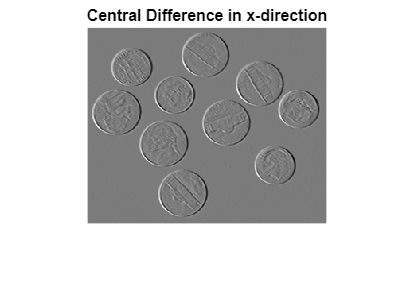

% TODO: Create the filter D and apply it to the image

% Define central difference kernel in x-direction
hx = [-0.5, 0, 0.5];
% Apply the filter using imfilter
img_dx = imfilter(coins, hx, 'replicate');  % replicate avoids edge artifacts

% Show the result
figure;
imshow(img_dx, []);
title('Central Difference in x-direction');

Now additionally determine the absolut value and perform tresholding (with a self-selected threshold).

Why do we use the absolut value?

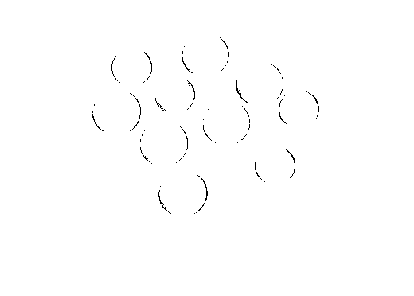

% TODO: perform tresholding

imshow(abs(imfilter(coins,hx))<0.2)

Proceed analogously along the $y$-direction, i.e. now use the finite difference filter $D_y := \frac12\,\left[ \begin{array}{r}
-1 \\ 
0 \\
1 \\ 
\end{array}\right]$.

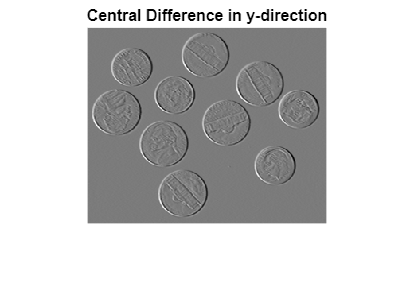

% TODO: along y-direction
hy = [-0.5; 0; 0.5];
% Apply the filter using imfilter
img_dy = imfilter(coins, hx, 'replicate');  % replicate avoids edge artifacts

% Show the result
figure;
imshow(img_dy, []);
title('Central Difference in y-direction');

Use the norm of the gradient $|\nabla u| = \sqrt{(u * D_x)^2 + (u*D_y)^2}$ as edge detector.

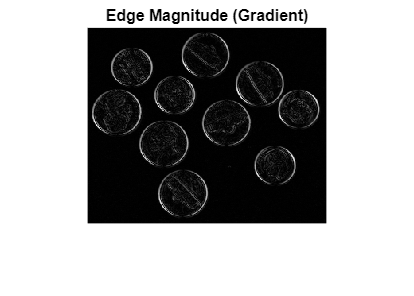

% TODO: norm of gradient as edge detector
edge_magnitude = sqrt(img_dx.^2 + img_dy.^2);

figure;
imshow(edge_magnitude, []);
title('Edge Magnitude (Gradient)');

b) **Laplace Filter**

Analogous to the difference filter, we can approximate the Laplace operator $\triangle f = \frac{\partial^2 f}{\partial x^2} + \frac{\partial^2 f}{\partial y^2}$ by finite differences. 

We obtain the matrix

$M = \frac14 \,\left( \begin{array}{rrr}
0 & 1 & 0 \\ 
1 & -4 & 1 \\
0 & 1 & 0 \\ 
\end{array}\right)$.

Apply the Laplace Filter to the image` coins.png `and perform tresholding (with a self-selected threshold).

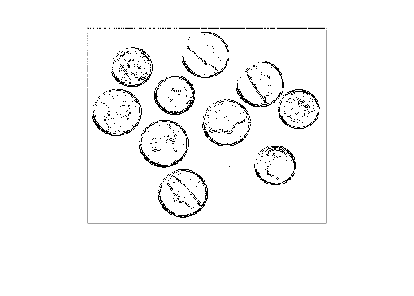

% TODO: Create mask M and apply it to the image
M = 0.25*[0,1,0;1,-4,1;0,1,0];
E = imfilter(coins,M);
imshow(abs(E)<0.05)

Alternatively, test the filter mask

$M = \frac18 \,\left( \begin{array}{rrr}
1 & 1 & 1 \\ 
1 & -8 & 1 \\
1 & 1 & 1 \\ 
\end{array}\right)$,

which is slightly better at detecting skew edges.

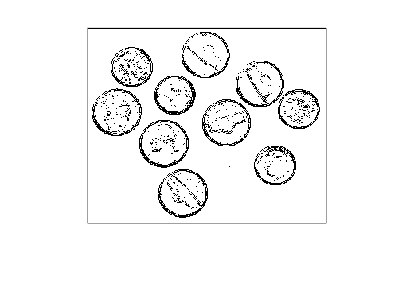

% TODO: Create mask M and apply it to the image
M = 0.125*ones(3); M(5)=-1;
E = imfilter(coins,M);
imshow(abs(E)<0.05)

c) **Sobel Filter**

Let the difference filter $D_x = \frac12\,[-1 ~ 0 ~ 1] $ along 1st dimension and the biomial filter $B_y = \frac14 \,\left[ \begin{array}{r}
1 \\ 
2 \\
1 \\ 
\end{array}\right]$ along 2nd dimension be given. Then we obtain the Sobel filter by the tensor product $S = D_x \otimes B_y$. This is another discrete approximation of the derivative.

Apply the Sobel filter

- along $x$-direction

- along $y$-direction

- by combination (norm of the gradient)

`to the image coins`. Determine the absolut value and perform tresholding (with a self-selected treshold).

% TODO: Create Sobel-Filter
D = 0.5*[-1 0 1];
binomial = 0.25*[1 2 1];
Sobel = kron(D,binomial');
Sobel

Sobel =    -0.1250         0    0.1250
   -0.2500         0    0.2500
   -0.1250         0    0.1250


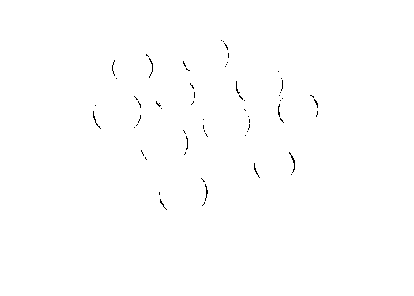

% TODO: apply along x-direction
Gx = conv2(coins,Sobel);
imshow(abs(Gx)<0.2)

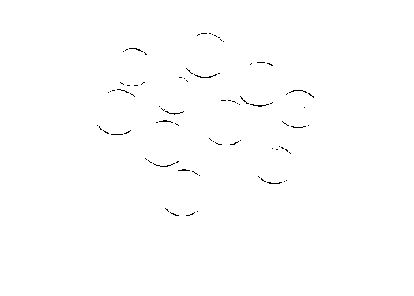

% TODO: apply along y-direction
Gy = conv2(coins,Sobel');
imshow(abs(Gy)<0.2)

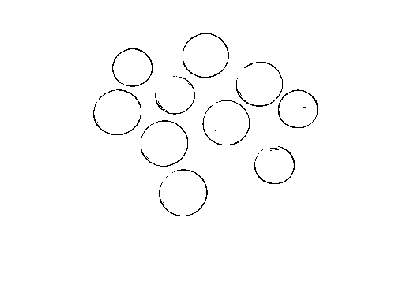

% TODO: norm of gradient
G = sqrt(Gx.^2+Gy.^2);
imshow(G<0.18)

Test the matlab function` edge `with the attribute` sobel`.

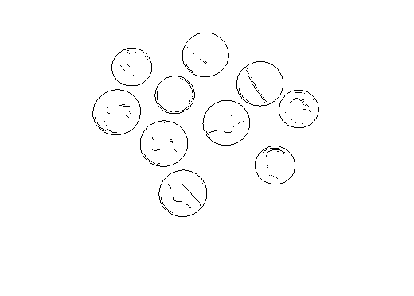

F = edge(coins,'sobel');
imshow(~F)

d) **Prewitt Filter**

Let the difference filter $D_x = \frac12\,[-1 ~ 0 ~ 1] $ along the 1st dimension and the filter $C_y = \frac13 \,\left[ \begin{array}{r}
1 \\ 
1 \\
1 \\ 
\end{array}\right]$ along the 2nd dimension be given. Then we obtain the Prewitt filter by the tensor product $S = D_x \otimes B_y$. This is another discrete approximation of the derivative.

Apply the Prewitt filter

- along the $x$-direction

- along the $y$-direction

- by combination (norm of the gradient)

 to the image` coins`, determine the absolute value and perform tresholding (with a self-selected threshold).

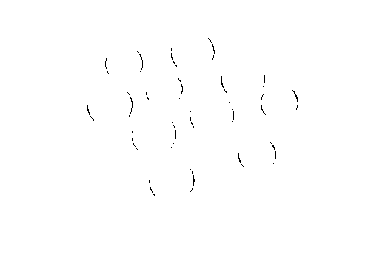

% TODO: Create Prewitt filter mask 
D = 0.5*[-1 0 1];
const = 1/3*[1 1 1];
Prewitt = kron(D,const');
% TODO: along x-direction
Gx = conv2(coins,Prewitt);
imshow(abs(Gx)<0.2)

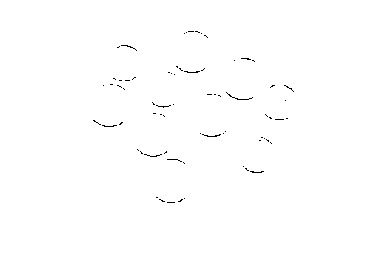

% TODO: along y-direction
Gy = conv2(coins,Prewitt');
imshow(abs(Gy)<0.2)

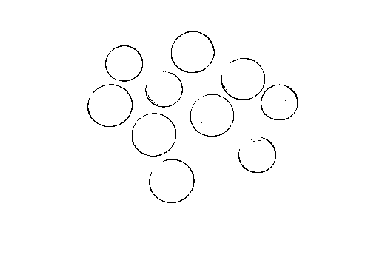

% TODO: norm of gradient
G = sqrt(Gx.^2+Gy.^2);
imshow(abs(G)<0.18)

Test the Matlab function` edge `with the attribute` prewitt`.

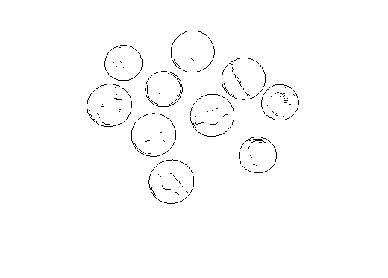

F = edge(coins,'prewitt');
imshow(~F)

#### Exercise 4: (Structure Tensor)

The structure tensor is a useful tool for finding edges and corners in images.

Let an 8-bit greyscale image  $U \colon \Omega \to F_{gr}$ with $\Omega \subset \mathbb{Z}^2, ~ |\Omega|<\infty$ be given. 

Lets consider $U$ has constant values in $x_0$ along some direction $r = (r_1,r_2)^T,~\|r\|_2=1$. Then 

$r^T\,\nabla U(x_0)=0$,             $(*)$

i.e. the directional derivative of $U$ in direction $r
$ is $0$. Since $U$ is defined on a discrete set, we use discrete partial derivatives for the gradient (see Exercise 3).

For noisy images we describe $(*)$ approximatively, for example, by the least squares problem


$$\min_{\|r\|_2=1} \left\{ \sum_{x\in\mathcal N(x_0)} G_\rho(x_0-x)\,(r^T\,\nabla U(x))^2 \right\}$$
      
$$(**)$$


where $G_{\rho}$ denotes a Gaussian filter (see Sheet 2 Exercise 3). We describe the neighbourhood $\mathcal N(x_0)$ of pixel $x_0$ (exactly like in sheet 2) by a mask of size $(2\cdot3\rho+1)\times(2\cdot3\rho+1)$. The pixels whose distance to the centre of the mask is greater than $3\rho$ are ignored again.

The symmetric positiv semidefinite matrix


$$J(x_0) = \sum_{x\in\mathcal N(x_0)} G_\rho(x_0-x)\,\nabla U(x)\,\nabla U(x)^T$$


leads $\min_{\|r\|_2=1} r^T\,J(x_0)\,r$ which is an equivalent problem to $(**)$. Hence $r$ is the eigenvector of the smallest eigenvalue of $J(x_0)$.

If $U$ is an image with gaussian noise, then we denoise $U$ at the beginning (before the computation of the gradient) with an gaussian filter with small variance $\sigma^2$, i.e.

$\nabla U_\sigma = \nabla (G_\sigma * U) = \nabla G_\sigma * U$.

For $\nabla U_\sigma(x_0) = (U_{\sigma,x}(x_0)\,,\,U_{\sigma,y}(x_0))^T$ we get

$J_\rho(x_0) = \sum\limits_{x\in\mathcal N(x_0)} G_\rho(x_0-x)\, \left(\begin{array}{cc} 
U_{\sigma,x}(x_0)^2 & U_{\sigma,x}(x_0)\,U_{\sigma,y}(x_0) \\ 
U_{\sigma,x}(x_0)\,U_{\sigma,y}(x_0) & U_{\sigma,y}(x_0)^2 \\ 
\end{array}\right)$.

The eigenvalues of $J(x_0)=\left( \begin{array}{rr}
a & b  \\ 
b & d  \\
\end{array}\right)
$ are the roots of the polynomial $(a-\lambda)(d-\lambda)-b^2 = 0$, i.e.

$\lambda_{1,2} = \frac12 \left( a+d \pm \sqrt{(a+d)^2-4(ad+b^2)} \right)$.

The eigenvector of the smallest eigenvalue reads as

$$ v_1 = \left( \begin{array}{cc}
-b \\
a-\lambda_1 \\ 
\end{array}\right)$
$.

The eigenvalues $\lambda_1\leq\lambda_2$ and the eigenvector $v_1$ are interpreted as follows:

- $\lambda_2 \gg \lambda_1$:         Edge in direction $v_1$

- $\lambda_1\approx\lambda_2\gg0$:  Corner

- $\lambda_1\approx\lambda_2\approx0$:   no structure

Implement the structure tensor. To do this, proceed as follows:

- Create the filter $\nabla G_\sigma$. Use the Sobel filter as approximation for the partial derivative and apply it to the Gaussian filter $G_\sigma$ with variance $\sigma^2=0.3$. (Hint: only generate in $x$-direction).

- Apply the resulting filter once in $x$-direction and once in $y$-direction to the image` img `and calculate the tensor components $U_{\sigma,x}(x_0)^2$ and $U_{\sigma,x}(x_0)\cdot U_{\sigma,y}(x_0) $ and $U_{\sigma,y}(x_0)^2$.

- Apply a Gaussian filter $G_\rho$ with standard deviation $\rho=\sqrt5$ to the tensor components.

- The tensor components are now the entries of the matrix $J_\rho(x_0)$, i.e. $a = G_\rho * U_{\sigma,x}(x_0)^2$ and $b=G_\rho*(U_{\sigma,x}(x_0)\cdot U_{\sigma,y}(x_0))$ and $d=G_\rho * U_{\sigma,y}(x_0)^2$. Compute the eigenvalues $\lambda_{1,2}$ and eigenvector $v_1$ of $J_\rho(x_0)$.

- Take a look at the plots. Moreover, test the structure thensor on the other images.

*Note:* Ignore the behaviour on the boundary of the image.

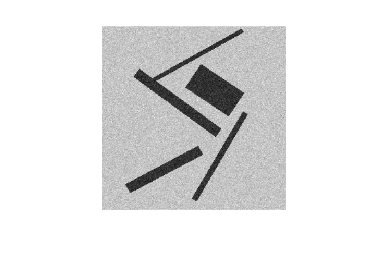

img = double(rgb2gray(imread('noisy_rectangles.jpg')))/255;
% img = double((imread('zone_plate.png')))/255;
% img = double(imread('coins.png'))/255;
% img = double(rgb2gray(imread('landscape.jpg')))/255;

imshow(img)

% 1) Construct the filter
% Construct Sobel-Filter
D = 0.5*[-1 0 1];
binomial = 0.25*[1 2 1];
Sobel = kron(D,binomial');

% Construct Gaussian mask (Sheet 2 Exercise 3)     [do not forget normalization]
sigma = sqrt(0.3);
s=floor(3*sigma);
[X,Y] = meshgrid(-s:s,-s:s);
R = sqrt(X.^2 + Y.^2);        % for every pixel: distance to central pixel
gauss = 1/sqrt(2*pi*sigma^2) * exp(-(R).^2/(2*sigma^2));
% truncate
gauss(R>3*sigma)=0;
% normalize
gauss = gauss ./ sum(gauss(:));

% Apply Sobel-Filter to Gaussian filter
Filter = conv2(gauss,Sobel);


% 2) Apply the generated filter to the image 
% along x-direction
Gx = conv2(img,Filter);
% along y-direction
Gy = conv2(img,Filter');
% Delete the boundary pixels
Gx = Gx(4:end-3,4:end-3);
Gy = Gy(4:end-3,4:end-3);
% compute Tensor components
XX = Gx.^2;
YY = Gy.^2;
XY = Gx .* Gy;


% 3) convolution = (weighted) sum with Gaussian filter
rho = sqrt(5);
XX = imgaussfilt(XX,rho);
XY = imgaussfilt(XY,rho);
YY = imgaussfilt(YY,rho);


% 4) Eigenvalues (positiv) and Eigenvectors
% TODO: Compute the Eigenvalues from the tensor components (use pointwise operations).
%       Write the larger eigenvalue in a matrix Lambda1 and the smaller eigenvalue in a matrix Lambda2.






% TODO: Compute the components of the eigenvector of the smaller eigenvalue.
% Name them v11 and v12.
% Normalize the eigenvectors to 1.







% 5) Interpretation
% plot the smaller eigenvalues
imagesc(Lambda1)

Unrecognized function or variable 'Lambda1'.

axis image off
colormap jet
colorbar
% plot the larger eigenvalues
imagesc(Lambda2)
axis image off
colorbar
colormap jet
% plot the directions (the eigenvectors)
% Therefore we plot the angle between the eigenvector and the vector (1,0)
% use the eigenvectors in 1st and 2nd quadrant and periodic colorbar
ind = v12<0;
v12(ind) = -v12(ind);
v11(ind) = -v11(ind);
angle = acos(v11);

imagesc(angle)
axis image off
colorbar
colormap hsv
set(gca, 'CLim', [0, pi])

#### Exercise 5: (Morphological Filters)

In the following we need the* Image Processing Toolbox *from Matlab (Home -> Add-Ons -> Image Processing Toolbox).

This will give us the commands` imdilate `and` imerode`.

Let a black-white valued image be given, that consists of black squares of different sizes of $k\times k$ pixels.

Implement a function

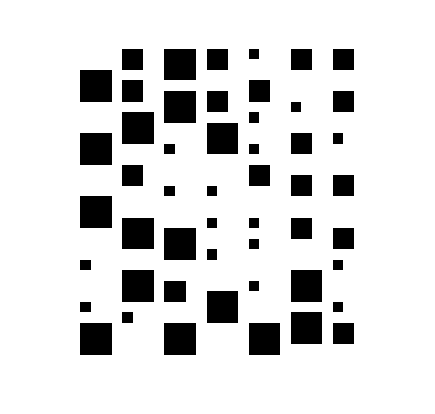

function nsquares = countSquares(A)
 l = min(size(A));
 nsquares = zeros(1,l);

 % TODO: Count the squares of different sizes in A. Define a structure
 % element strel and use the commands imdilate and imerode.

lengthOfSide =      1     2     3


count =     18    17    16


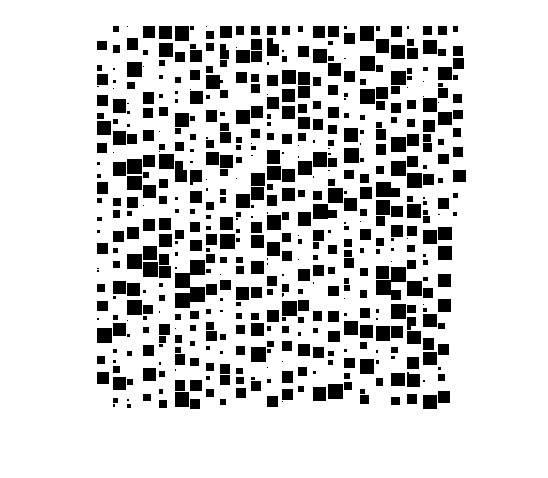

 for k = l:-1:1
 % Define structure element
 S = strel('square',k);

 % dilation and count the squares of size k x k
 X = imdilate(A,S);

lengthOfSide =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


count =     39    31    24    23    33    35    27    30    23    25    33    24    32    30    35    26    26    28    28    24


 nsquares(k) = sum(X(:)==0);
 % delete this squares from A
  A(imerode(X,S)==0) = uint8(255);
 end
end

based on morphological operations that generates a vector` nsquares `to an given image` A`.

The entry` nsquares(k) `should reflect the number of $k\times k$ squares in the image` A`.

Use the commands` imdilate `and` imerode `(define the structure element with` strel`). 

Now test your code on the following examples.

X = imread('squares1.png');
imshow(X)
truesize([300,300])
nsquares1 = countSquares(X);
[~,lengthOfSide,count] = find(nsquares1)

X = imread('squares2.png');
imshow(X)
nsquares2 = countSquares(X);
[~,lengthOfSide,count] = find(nsquares2)